% CODE DESCRIPTION:
% This code iterates through each trial and each subject, running the
% AnimationGen.m function for every one. AnimationGen.m reads the Qualisys
% data file for the subject/trial combo fed to it, then generates four 3-D
% plots of the marker positions which update every .01 seconds to the next
% time-step in the data file. Each update is captured as a frame in an
% animation of the marker positions. The first plot shows the animation 
% from a top view, the second plot shows an orthographic view, the third
% plot shows a view normal to the back, and the fourth plot shows a side
% view.

% Subject list
sn={'S01';'S02';'S04';'S05';'S06';'S07';'S08';'S09';'S10';'S11'
    'S12';'S13';'S14';'S15';'S16';'S17';'S18';'S19';'S20';'S21'
    'S22';'S23';'S24';'S25';'S26';'S27';'S29';'S30'}; % Subjects 3 and 28 exluded due to spinal pathologies
% sn={'S03';'S28'}; % Only unhealthy subjects
% Trial list
tn={'Flex_1';       'Flex_2';       'Flex_3'        % 1-3
    'Flex_box_1';   'Flex_box_2';   'Flex_box_3'    % 4-6
    'ExBa_Flex_1';  'ExBa_Flex_2';  'ExBa_Flex_3'   % 7-9
    'Flex_L_1';     'Flex_L_2';     'Flex_L_3'      % 10-12
    'Box_L_1';      'Box_L_2';      'Box_L_3'       % 13-15
    'Flex_R_1';     'Flex_R_2';     'Flex_R_3'      % 16-18
    'Box_R_1';      'Box_R_2';      'Box_R_3'       % 19-21
    'Ext_N_1';      'Ext_N_2';      'Ext_N_3'       % 22-24
    'ExBa_Ext_1';   'ExBa_Ext_2';   'ExBa_Ext_3'    % 25-27
    'Ext_L_1';      'Ext_L_2';      'Ext_L_3'       % 28-30
    'Ext_R_1';      'Ext_R_2';      'Ext_R_3'       % 31-33
    'ExBa_Cont_1';  'ExBa_Cont_2';  'ExBa_Cont_3'   % 34-36
    'SideL_1';      'SideL_2';      'SideL_3'       % 37-39
    'SideR_1';      'SideR_2';      'SideR_3'       % 40-42
    'RotationL_1';  'RotationL_2';  'RotationL_3'   % 43-45
    'RotationR_1';  'RotationR_2';  'RotationR_3'   % 46-48
    'UpnGo_1';      'UpnGo_2';      'UpnGo_3'};     % 49-51

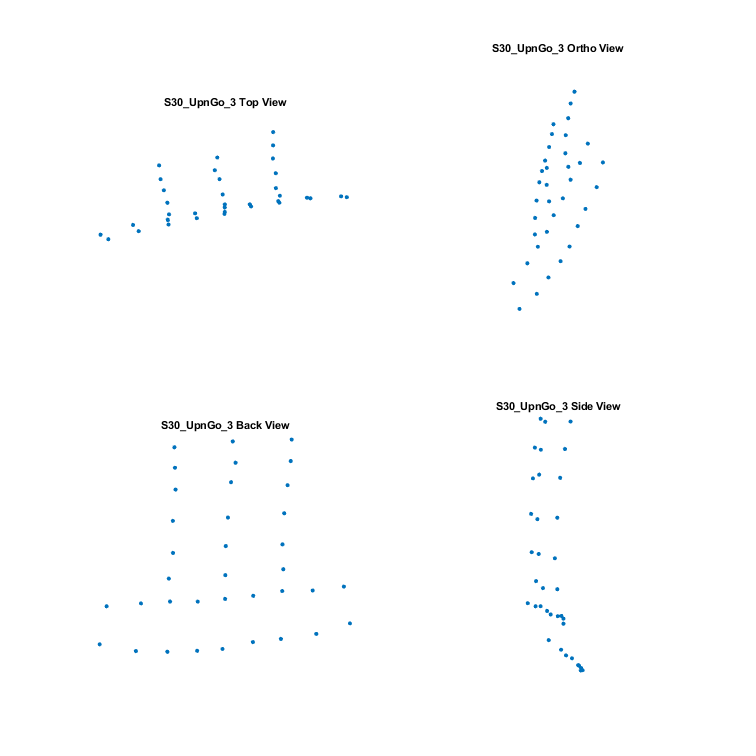

%%%% ANIMATION GENERATION %%%%

% Specify folder where the AnimationGen.m function is saved
addpath('C:\Users\gelde\Documents\BACPAC\MATLAB');

for j=28:28 % Iterate through specified subjects
% for j=1:numel(sn) % Iterate through each subject (28 total)
    % Specify folder where subjects' data is located (concatenate subject number to folder path)
    InputFolder=strcat('C:\Users\gelde\Documents\BACPAC\Data Backup\',sn{j});
    addpath(InputFolder);
    % Specify the subjects' output folder.
    OutputFolder=strcat('C:\Users\gelde\Box\BACPAC Biomechanics and System Validation\Biomechanics MATLAB Subjects 1-30\Output\',sn{j});
    cd(OutputFolder);
%     for i=1:31 % Iterate through selected trials
    for i=1:numel(tn) % Iterate through each trial (0-3 per subject for each exercise)
        if isfile([InputFolder '\' tn{i} '.mat'])
%             AnimationGen_Experimental(tn{i},sn{j}); % Generate the animations
            AnimationGen(tn{i},sn{j}); % Generate the animations
        end
    end
    % Remove the input folder before adding a new one at the reinitialization of the loop
    rmpath(InputFolder);
end